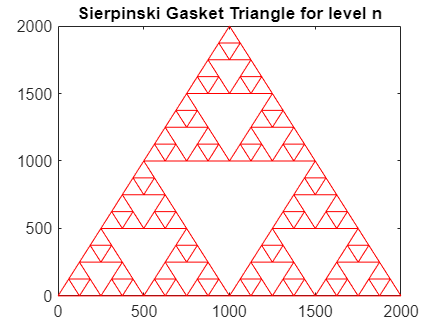

% 'm' is the outter level SGT and 'n' is the inner level SGT.
% Input: m,n are non-zero positive integers; m < n
% Output: SGT graphs for m and n levels

l = []; %an arbitary matrix used to store the nodes in draw_n and draw_m functions
n = 4; %inner level
m = 1; % outter level
left_node = [0 0]; %starting cordinates of left node
top_node = [1000 2000]; %starting cordinates of top node
right_node = [2000 0]; %starting cordinates of right node

nodes_n = draw_n(n+1,left_node, top_node,right_node,l); %drawing SGT for level n matrix and finding its nodes
hold off


nodes_n = unique(nodes_n,'rows','stable') %removing the cordinates of the repeated nodes in level n

nodes_n = 1.0e+03 *

         0         0
    0.0625    0.1250
    0.1250         0
    0.1250    0.2500
    0.1875    0.1250
    0.2500         0
    0.1875    0.3750
    0.2500    0.2500
    0.2500    0.5000
    0.3125    0.3750



vertices_triangles_m = draw(m+1,left_node, top_node,right_node,l) %drawing SGT for level m matrix and finding its nodes(vertices)

vertices_triangles_m =            0        1000        1000           0
         500        1500        2000        1000
        1000        2000        1000           0


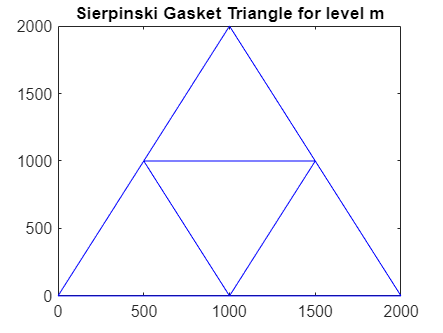

hold off

## Draw SGT for n

%draws the adjacency matrix for level n and returns all the nodes of level
%n
%this is a recursive funtion
%input: level n, left node, top node, right node and empty list
%ouput: graph of SGT and node matrix for n

function e = draw_n(n,left_node, top_node,right_node,l)
    if n == 1 %if the level is 1, it is the lowest level
        x = [left_node(1),top_node(1),right_node(1),left_node(1)];
        y = [left_node(2),top_node(2),right_node(2),left_node(2)];
        plot(x,y,"r-") % plots the triangle
        title("Sierpinski Gasket Triangle for level n")
        %upates the matrix l with the new nodes
        l = [l;left_node];
        l = [l;top_node];
        l = [l;right_node];
        hold on
    else %if not at the lowest level, find the nodes of the inner triangle
        % when searching for the inner triangle, new nodes have to be found
        left_top_mid = midpoint(left_node,top_node);
        top_right_mid = midpoint(top_node, right_node);
        left_right_mid = midpoint(left_node, right_node);

        l=draw_n(n - 1,left_node,left_top_mid,left_right_mid ,l);
        l=draw_n(n - 1,left_top_mid,top_node,top_right_mid,l);
        l=draw_n(n - 1,left_right_mid, top_right_mid,right_node,l);
    end
    e = l; %retunrs the list with node cordinates
end

## Midpoint

%finds the midpoint of two given points
%input: point1, point2
%output: midpoint of x and y cordinates

function point = midpoint(point1,point2)
    x = (point1(1)+point2(1))/2;
    y = (point1(2)+point2(2))/2;
    point = [x,y];
end

## Draw SGT for m

%draws the adjacency matrix for level m and returns all the nodes(vertices) of level
%m
%this is a recursive funtion
%input: level m, left node, top node, right node and empty list
%ouput: graph of SGT and node matrix for m

function e = draw(n,left_node, top_node,right_node,l)
    if n == 1
        x = [left_node(1),top_node(1),right_node(1),left_node(1)];
        y = [left_node(2),top_node(2),right_node(2),left_node(2)];
        m = [left_node(1) right_node(1) top_node(2) right_node(2)];
        plot(x,y,"b-")
        title("Sierpinski Gasket Triangle for level m")
        %upates the matrix l with the new nodes
        l = [l;m];
        hold on
    else %if not at the lowest level, find the nodes of the inner triangle
        % when searching for the inner triangle, new nodes have to be found
        left_top_mid = midpoint(left_node,top_node);
        top_right_mid = midpoint(top_node, right_node);
        left_right_mid = midpoint(left_node, right_node);

        l=draw(n - 1,left_node,left_top_mid,left_right_mid ,l);
        l=draw(n - 1,left_top_mid,top_node,top_right_mid,l);
        l=draw(n - 1,left_right_mid, top_right_mid,right_node,l);
    end
    e = l; %retunrs the list with node cordinates
end